## `Desarrollo y Codigo`

# **Ejercicio 1**

Carga el conjunto de datos de la flor Iris

load fisheriris

Selecciona las cuatro variables numéricas

sepal_length = meas(:, 1);  % Longitud del sépalo
sepal_width = meas(:, 2);   % Ancho del sépalo
petal_length = meas(:, 3);  % Longitud del pétalo
petal_width = meas(:, 4);   % Ancho del pétalo
variables_numericas = meas(:, 1:4);

Calcula la matriz de correlación entre estas variables utilizando un método adecuado

matriz_correlacion = corrcoef(variables_numericas);  
disp('Matriz de correlación:');

Matriz de correlación:


disp(matriz_correlacion)

    1.0000   -0.1176    0.8718    0.8179
   -0.1176    1.0000   -0.4284   -0.3661
    0.8718   -0.4284    1.0000    0.9629
    0.8179   -0.3661    0.9629    1.0000



Identifica pares de variables que presenten una correlación positiva significativa

umbral = 0.7;
matriz_correlacion = corrcoef(variables_numericas);
nombres_variables = {'Longitud del sépalo', 'Ancho del sépalo', 'Longitud del pétalo', 'Ancho del pétalo'};

% Pares con correlación positiva significativa
disp('Pares de variables con correlación positiva significativa:');

Pares de variables con correlación positiva significativa:


for i = 1:size(matriz_correlacion, 1)
    for j = i+1:size(matriz_correlacion, 2)
        if matriz_correlacion(i, j) > umbral
            fprintf('%s y %s: %.4f\n', nombres_variables{i}, nombres_variables{j}, matriz_correlacion(i, j));
        end
    end
end

Longitud del sépalo y Longitud del pétalo: 0.8718
Longitud del sépalo y Ancho del pétalo: 0.8179
Longitud del pétalo y Ancho del pétalo: 0.9629


Visualiza estas correlaciones utilizando un mapa de calor

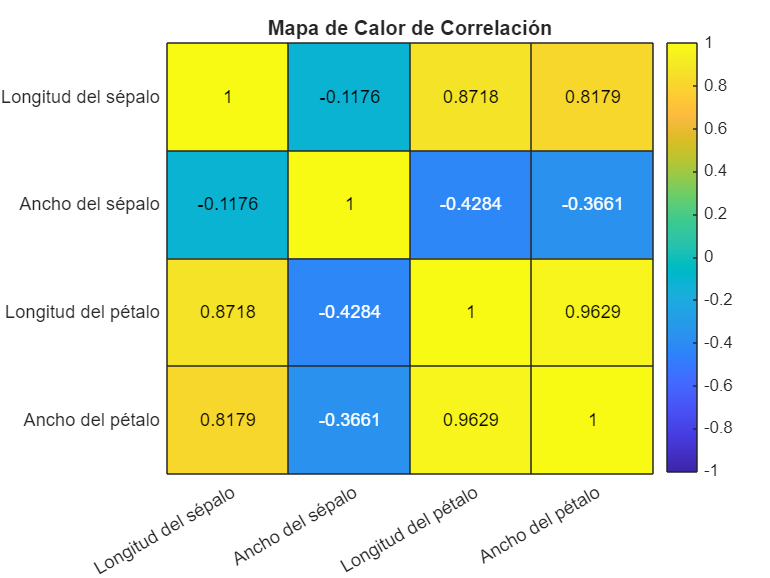

% Crear un mapa de calor
hold off;
heatmap(nombres_variables, nombres_variables, matriz_correlacion, ...
        'Colormap', parula, ...  
        'ColorLimits', [-1, 1], ... 
        'Title', 'Mapa de Calor de Correlación', ...
        'ColorbarVisible', 'on'); 

¿Qué pares de variables muestran una correlación positiva fuerte?

Los que mas presentan una correlacion positiva son la longitud del petalo con la longitud del sepalo, el ancho del petalo con longitud del sepalo y la longitud del petalo con el ancho del petalo.

¿Cómo podrían estas correlaciones estar relacionadas con las características de las diferentes especies de Iris?

Las correlaciones positivas fuertes indican que cuando una variable aumenta, la otra también tiende a aumentar de manera proporcional. En el caso de las especies de Iris si tiene petalos mas largos es mas probable que tenga sepalos mas largos; a medida que el sepalo crece en longitud , el petalo tambien aumenta en lo ancho y a mayor longitud del petalo tambien existe un mayor ancho.

Repite el analisis separando los datos por especie (setosa, versicolor, virginica) para ver si las correlaciones varían entre ellas.

% Separar los datos por especie
indices_setosa = strcmp(species, 'setosa');
indices_versicolor = strcmp(species, 'versicolor');
indices_virginica = strcmp(species, 'virginica');

% Datos para cada especie
setosa_data = meas(indices_setosa, :);
versicolor_data = meas(indices_versicolor, :);
virginica_data = meas(indices_virginica, :);

% Función para calcular y visualizar la matriz de correlación
function plot_correlation_heatmap(data, nombres_variables, titulo)
    matriz_correlacion = corrcoef(data);
    figure;  
    heatmap(nombres_variables, nombres_variables, matriz_correlacion, ...
            'Colormap', parula, ...
            'ColorLimits', [-1, 1], ...
            'Title', titulo, ...
            'ColorbarVisible', 'on');
end

Setosa 

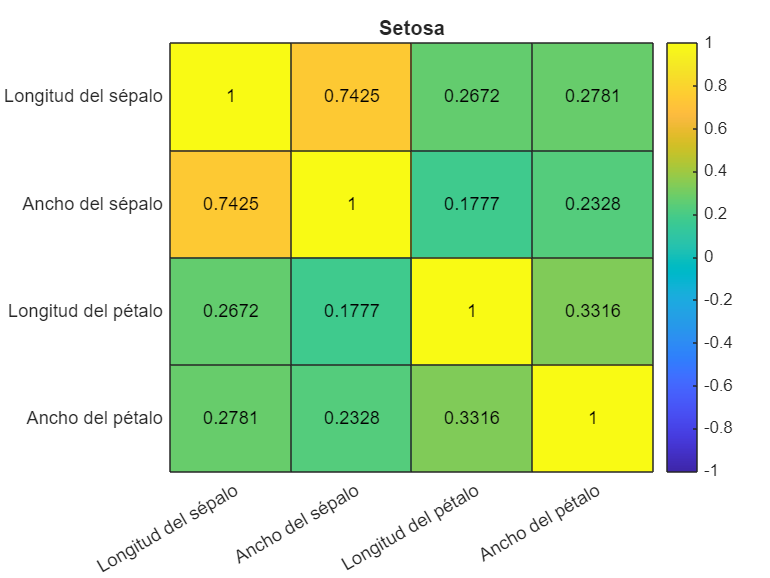

plot_correlation_heatmap(setosa_data, nombres_variables, 'Setosa');

Versicolor 

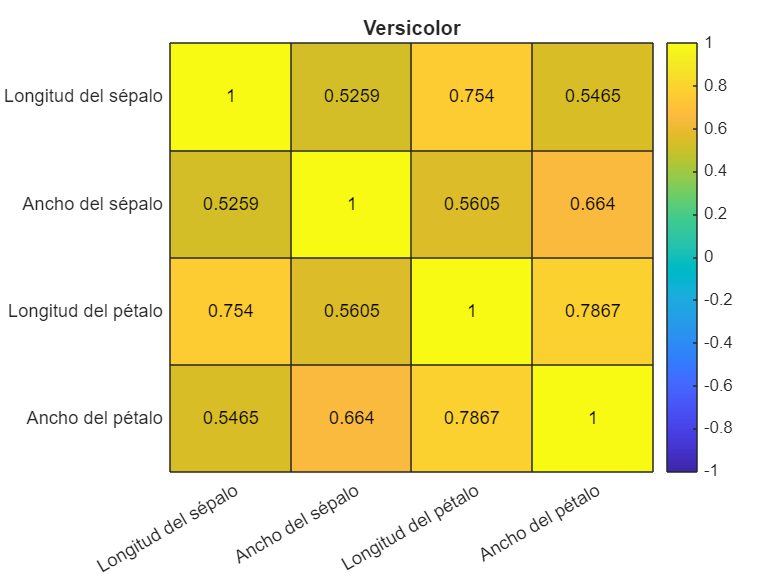

plot_correlation_heatmap(versicolor_data, nombres_variables, 'Versicolor');

Virginica

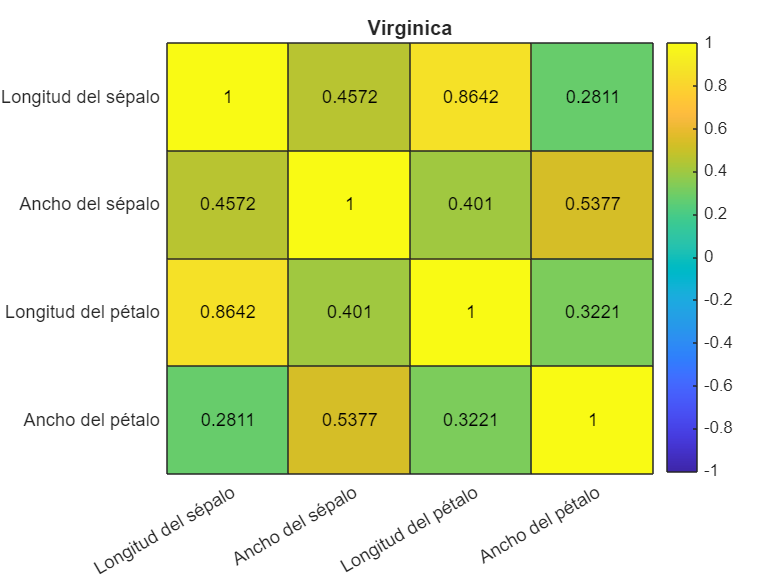

plot_correlation_heatmap(virginica_data, nombres_variables, 'Virginica');

Podemos ver que para cada una varia de distinta manera pero todas tienen una correlacion positiva, en algunas es mayor esa correlacion y en otras es mas debil.

# Ejercicio 2 

Cargar imagen 

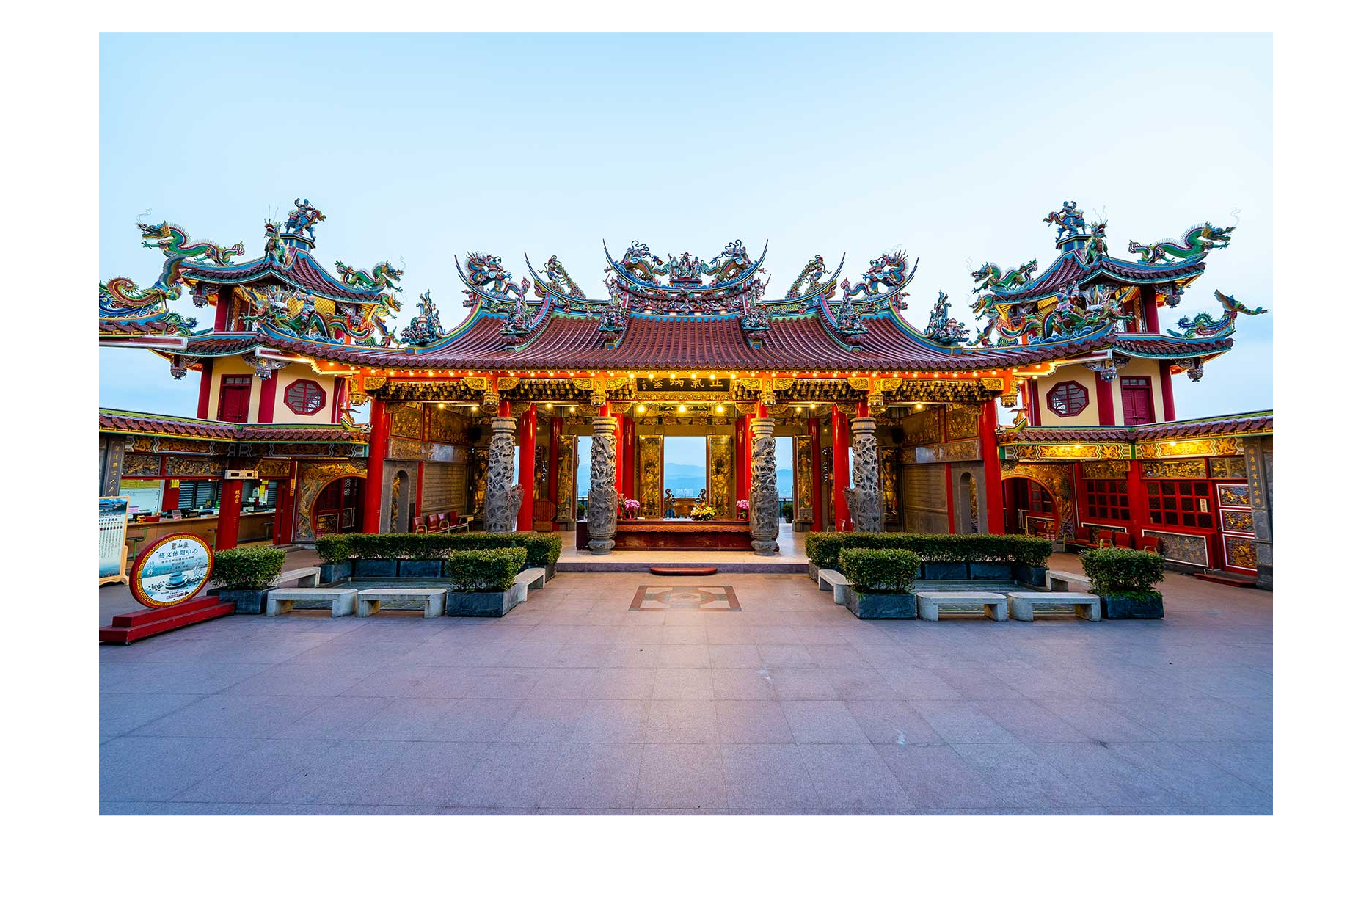

img = imread('templo.jpg'); % Cargar la imagen
imshow(img); % Mostrar la imagen

Convierte la imagen a escala de grises si es necesario.

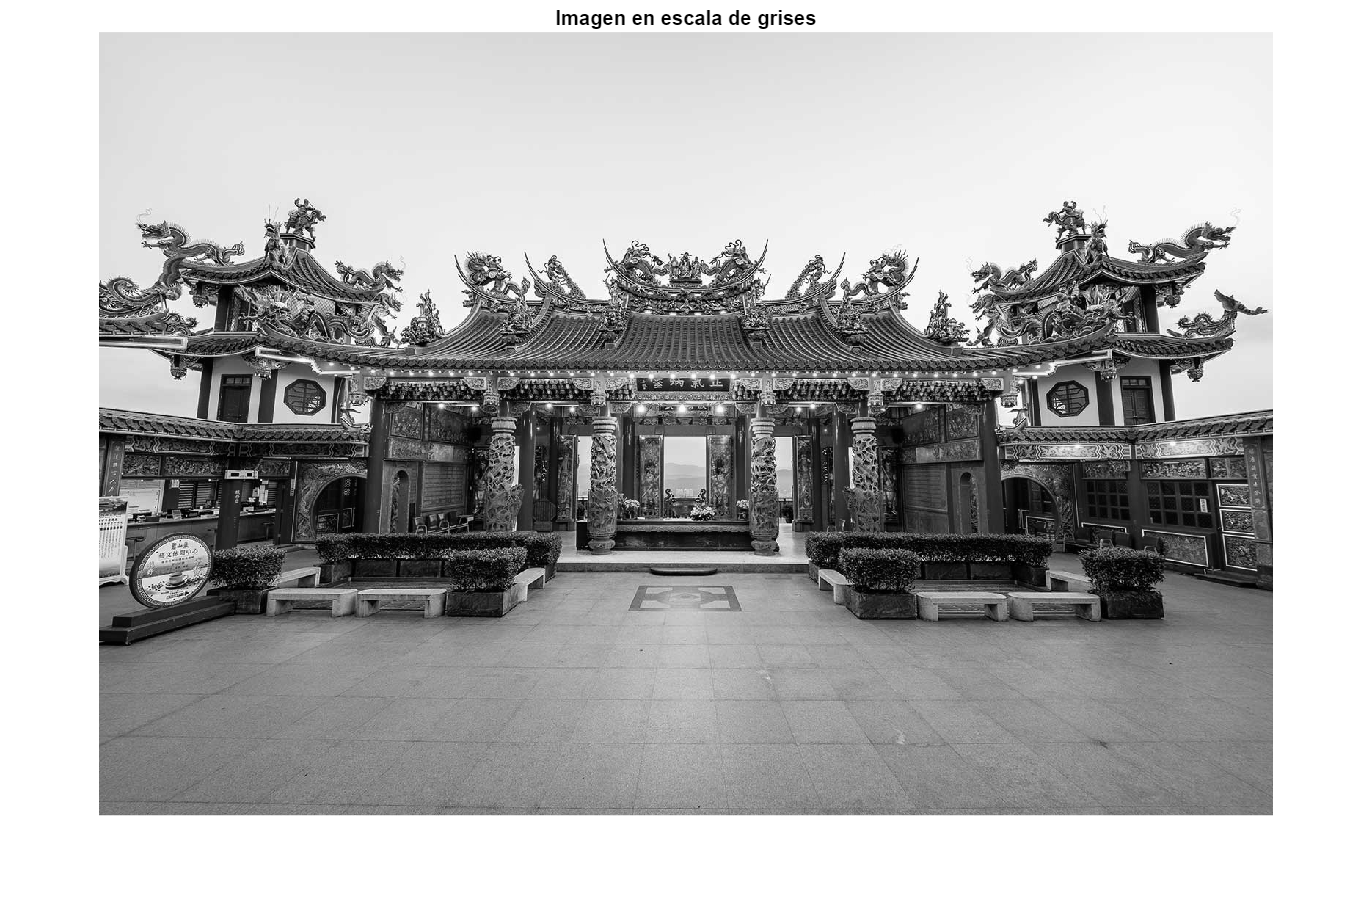

if size(img, 3) == 3
    img_gray = rgb2gray(img);
else
    img_gray = img;
end
figure;
imshow(img_gray);
title('Imagen en escala de grises');

Aplicamos el filtro Gaussiano para reducir el ruido.

img_smooth = imgaussfilt(img_gray, 3);
figure;
imshow(img_smooth);

Utiliza el operador de Sobel para detectar bordes en la imagen.

% Detección de bordes usando el operador de Sobel
edges = edge(img_smooth);

% Mostrar la imagen con bordes detectados
figure;
imshow(edges);
title('Detección con Sobel');

Ahora vamos a analizar los bordes extraidos 

figure;
imshow(img_gray);
hold on;
visboundaries(edges, 'Color', 'r');
title('Bordes Superpuestos en la Imagen Original');
hold off;

figure;
imhist(img_gray);
title('Histograma de Intensidad de la Imagen Original');

Veamos que existe una alta concentración de píxeles en la zona de los valores máximos de intensidad, hay una distribución más uniforme en valores bajos y un pico notable en valores altos

Utiliza la transformada de Hough para detectar líneas o círculos en la imagen. Extrae propiedades de regiones utilizando region-props.

%Con lineas 
[H, theta, rho] = hough(edges);
peaks = houghpeaks(H, 90);
lines = houghlines(edges, theta, rho, peaks);

% Mostrar la imagen con líneas detectadas
figure;
imshow(img_gray); hold on;
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'red');
end
title('Líneas Detectadas (Hough)'); 
hold off;

# Ejercicio 3

Utilizar la funcion ECG de MATLAB o generar una onda sintética con sumas de senoidales. Una forma común es combinar ondas sinusoidales y pulsos para representar las ondas P, QRS y T de un ECG.

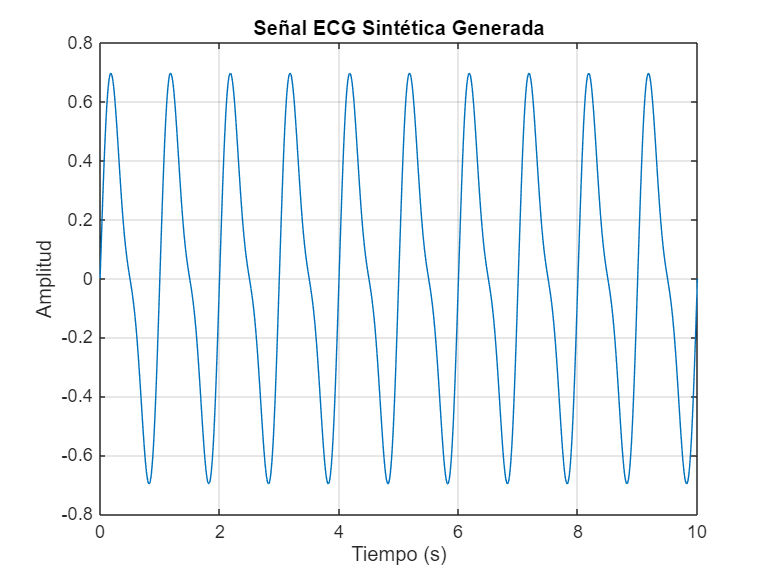

fs_muestreo = 1000;  % Frecuencia de muestreo (Hz)
tiempo = 0:1/fs_muestreo:10;  % Tiempo de 10 segundos
frecuencia_picosR = 1.0;  % Frecuencia de los picos R del ECG (1 Hz aprox.)
frecuencia_pqrs = 2;  % Frecuencia de las ondas P, QRS, T

% Generación de la señal sintética de ECG (sumando sinusoides)
senal_ecg = 0.6 * sin(2*pi*frecuencia_picosR*tiempo) + 0.2 * sin(2*pi*frecuencia_pqrs*tiempo);

% Señal generada
figure;
plot(tiempo, senal_ecg);
title('Señal ECG Sintética Generada');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

Simular ruido de alta frecuencia (por ejemplo, ruido de 60 Hz de interferencia el ́ectrica) y ruido aleatorio (ruido gaussiano).

ruido_60hz = 0.3 * sin(2*pi*60*tiempo);  % Ruido de 60 Hz 
ruido_gaussiano = 0.1 * randn(size(tiempo));  
senal_ecg_ruidosa = senal_ecg + ruido_60hz + ruido_gaussiano;

Utilizar la Transformada Rápida de Fourier (FFT) para analizar las componentes de frecuencia de la señal con ruido.

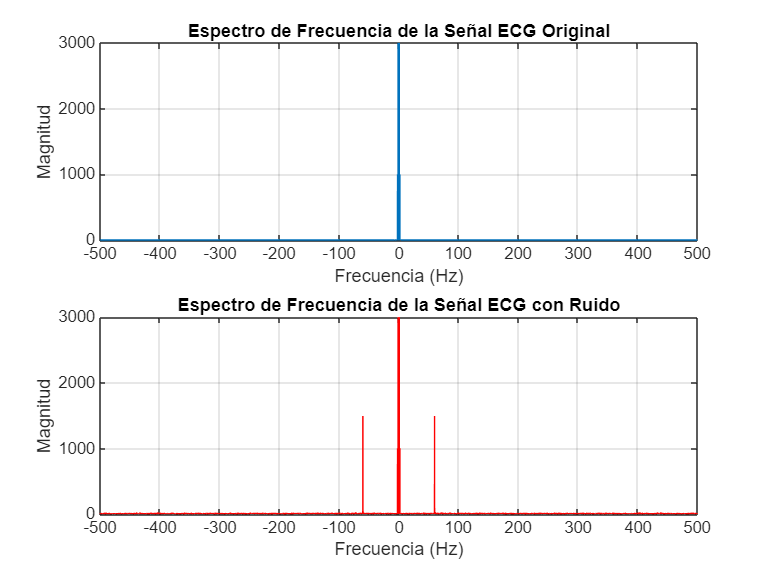

N_muestras = length(tiempo);
frecuencias = (-N_muestras/2:N_muestras/2-1)*(fs_muestreo/N_muestras);  
fft_ecg = fftshift(fft(senal_ecg));  
fft_ecg_ruidosa = fftshift(fft(senal_ecg_ruidosa));
figure;
subplot(2,1,1);
plot(frecuencias, abs(fft_ecg));
title('Espectro de Frecuencia de la Señal ECG Original');
xlabel('Frecuencia (Hz)'); ylabel('Magnitud'); grid on;

subplot(2,1,2);
plot(frecuencias, abs(fft_ecg_ruidosa), 'r');
title('Espectro de Frecuencia de la Señal ECG con Ruido');
xlabel('Frecuencia (Hz)'); ylabel('Magnitud'); grid on;

Filtro para eliminar el ruido de alta frecuencia

frecuencia_corte = 40;  % Filtro pasa-bajos 
[b_filtro, a_filtro] = butter(6, frecuencia_corte / (fs_muestreo/2), 'low');  % Filtro Butterworth de 6° orden
senal_ecg_filtrada = filter(b_filtro, a_filtro, senal_ecg_ruidosa);

Descripción de los pasos realizados.

- Se generó una señal sintética de ECG combinando sinusoides 

- Se añadió ruido eléctrico de 60 Hz y ruido gaussiano 

- Se realizó la FFT para analizar el espectro de frecuencia 

- Se diseñó un filtro pasa-bajos con frecuencia de corte de 45 Hz

-  Se compararon las señales original, con ruido y filtrada

– Resultados obtenidos (gráficos y análisis)

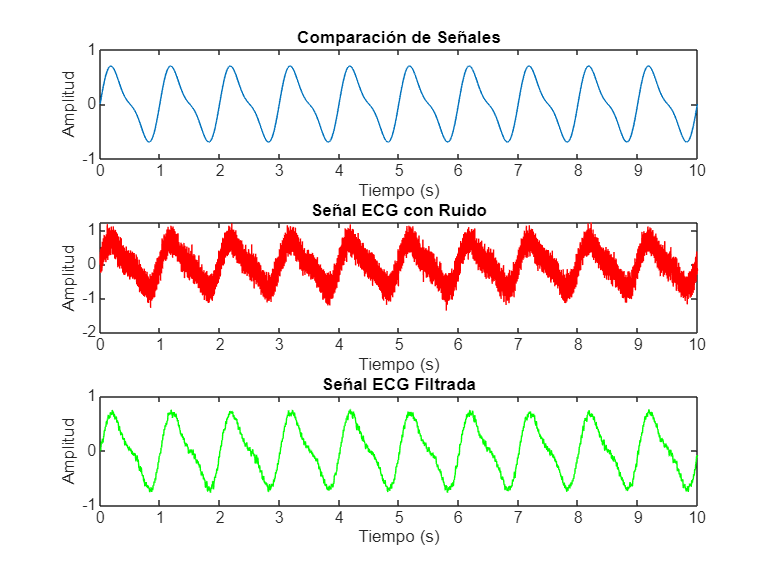

figure;
subplot(3,1,1);
plot(tiempo, senal_ecg);
title('Señal ECG Original');
xlabel('Tiempo (s)'); ylabel('Amplitud');

title('Comparación de Señales');
subplot(3,1,2);
plot(tiempo, senal_ecg_ruidosa, 'r');
title('Señal ECG con Ruido');
xlabel('Tiempo (s)'); ylabel('Amplitud');

subplot(3,1,3);
plot(tiempo, senal_ecg_filtrada, 'g');
title('Señal ECG Filtrada');
xlabel('Tiempo (s)'); ylabel('Amplitud');

– Discusión sobre la efectividad del filtrado en la eliminación del ruido

- Veamos que la primer grafica nos muestra una señal suave con oscilaciones, lo que sugiere que podría ser la señal ECG ideal o una referencia.

- En la segunda grafica vemos una señal con oscilaciones más pronunciadas y una gran cantidad de ruido superpuesto.Ahora bien , el ruido en la forma de variaciones rápidas y de alta frecuencia, lo que puede afectar el análisis correcto del ECG.

- La tercra vemos una reducción significativa del ruido, con una señal más limpia y suave, veamos que la forma de la onda se mantiene similar a la señal original, lo que indica que el filtrado ha sido efectivo al eliminar el ruido sin distorsionar en exceso la señal útil

Por lo que el filtrado ha sido efectivo en la eliminación del ruido, ya que la señal final es más limpia y mantiene su forma original. 

Crea un filtro para eliminar el ruido de alta frecuencia y compara los resultados.

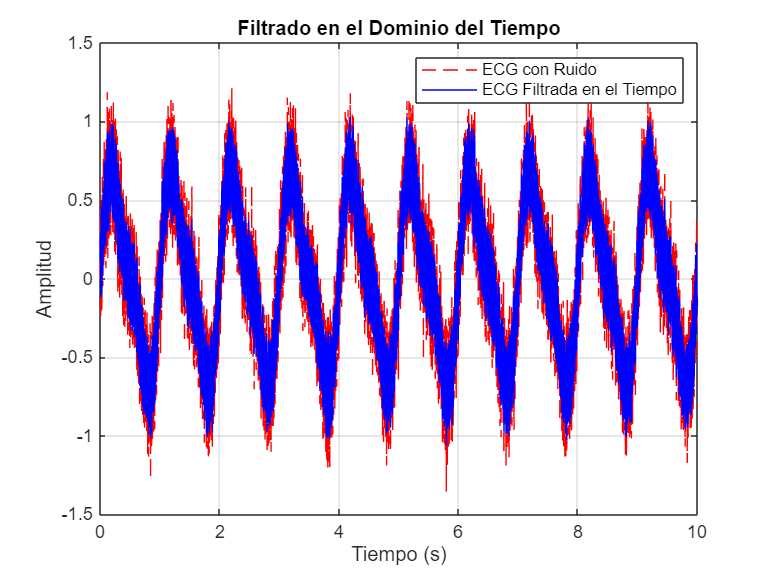

ventana = 5;  % Tamaño de la ventana del filtro
senal_ecg_suavizada = movmean(senal_ecg_ruidosa, ventana);

figure;
plot(tiempo, senal_ecg_ruidosa, 'r--'); hold on;
plot(tiempo, senal_ecg_suavizada, 'b');
title('Filtrado en el Dominio del Tiempo');
xlabel('Tiempo (s)'); ylabel('Amplitud');
legend('ECG con Ruido', 'ECG Filtrada en el Tiempo');
grid on;

## `Concluiones `

En esta práctica, aprendí a analizar la correlación entre variables dentro del conjunto de datos Iris, lo que me permitió comprender mejor cómo se relacionan ciertos atributos entre sí. Esta habilidad no solo es útil para este conjunto de datos en particular, sino que también se puede aplicar en otros contextos donde sea necesario interpretar la relación entre distintas variables. Identificar estas correlaciones puede ser clave en áreas como la biología, la estadística y el aprendizaje automático.

Además, trabajé con imágenes para extraer características relevantes. Aprendí a convertir imágenes a escala de grises y aplicar filtros como el filtro gaussiano para suavizarlas y resaltar estructuras importantes, como los bordes. Esto me permitió generar histogramas y comparar distribuciones de intensidad entre distintas imágenes, lo cual es útil en aplicaciones como reconocimiento de patrones y análisis de similitud entre imágenes.

Otro aspecto clave fue el procesamiento de señales, donde profundicé en el uso de la Transformada de Fourier. Esta herramienta es fundamental para analizar la composición en frecuencia de una señal y extraer información valiosa. Aprendí cómo aplicar filtros para reducir ruido en señales e imágenes y evalué si la eliminación del ruido afecta la información relevante. Este proceso es especialmente importante en el análisis de señales biomédicas, como el ECG, donde es crucial mantener los componentes esenciales de la señal sin introducir distorsiones.

En general, esta práctica me permitió desarrollar habilidades en análisis de datos, procesamiento de imágenes y señales, así como en la interpretación de información extraída a partir de distintos métodos. Estas técnicas tienen aplicaciones en diversos campos, desde el procesamiento de imágenes médicas hasta el análisis de datos en ingeniería y ciencia. La práctica me ayudó a fortalecer mi capacidad para aplicar herramientas matemáticas y computacionales en la extracción y análisis de información útil.

## `Referencias `

- ` Gonzalez, R., Woods, R., Digital Image Processing, Prentice Hall, 2008.`

- `Pratt, W. k., Digital Image Processing, John Wiley and Sons Inc, 2001.`

- `Jahne, B., Digital Image Processing, Springer, 2005.`

- `S ́anchez Garreta, Josep Salvador; Garc ́ıa, Vicente. Special Issue on Data Preprocessing in Pattern Recognition: Recent Progress, Trends and Applications. 2022.`

- `Majidi, Mehrdad; Oskuoee, Mohammad. Improving pattern recognition accuracy of partial discharges by new data preprocessing methods. Electric Power Systems Research, 2015, vol. 119, p. 100-110.`

- `Lotfi, Safia, et al. Recent progress on the synthesis, morphology and photocatalytic dye degradation of BiVO4 photocatalysts: A review.Catalysis Reviews, 2024, vol. 66, no 1, p. 214-258.`